# sub-20

This code begins by importing raw SEEG data and converting to Fieldtrip format. 

It then edit the SEEG channel labels, inspects the SEEG data, and remove any bad channels.

Following this, the code redefines resting, 0-back, 1-back and 2-back blocks using TRIG or Event channel signals.   

## Set working directory

clc;clear;close all;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\fieldtrip-20231220;
ft_defaults;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\iEEGPrep
iEEGPrep_initial;
cd  Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS;
subID = 'sub-20';
cd(fullfile(subID, 'ieeg'));

## Import SEEG data and edit channel labels

iEEGpath = [subID, '_task-nback_run-1_ieeg.edf'];
cfg = [];
cfg.dataset = iEEGpath;
Data = ft_preprocessing(cfg);

found matching BIDS sidecar 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-20\ieeg\sub-20_electrodes.tsv'
reading 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-20\ieeg\sub-20_electrodes.tsv'


 In ft_read_header at line 2937
 In ft_preprocessing at line 391

processing channel { 'Event' 'ta'1' 'ta'2' 'ta'3' 'ta'4' 'ta'5' 'ta'6' 'ta'7' 'ta'8' 'ta'9' 'ta'10' 'th'1' 'th'2' 'th'3' 'th'4' 'th'5' 'th'6' 'th'7' 'th'8' 'th'9' 'th'10' 'th'11' 'th'12' 'tb'1' 'tb'2' 'tb'3' 'tb'4' 'tb'5' 'tb'6' 'tb'7' 'tb'8' 'tb'9' 'tb'10' 'tb'11' 'tb'12' 'st'1' 'st'2' 'st'3' 'st'4' 'st'5' 'st'6' 'st'7' 'st'8' 'st'9' 'st'10' 'st'11' 'st'12' 'ti'1' 'ti'2' 'ti'3' 'ti'4' 'ti'5' 'ti'6' 'ti'7' 'ti'8' 'ti'9' 'ti'10' 'b'1' 'b'2' 'b'3' 'b'4' 'b'5' 'b'6' 'b'7' 'b'8' 'b'9' 'b'10' 'f'1' 'f'2' 'f'3' 'f'4' 'f'5' 'f'6' 'f'7' 'f'8' 'f'9' 'f'10' 'f'11' 'f'12' 'mf'1' 'mf'2' 'mf'3' 'mf'4' 'mf'5' 'mf'6' 'mf'7' 'mf'8' 'mf'9' 'mf'10' '

Data = rmfield(Data, 'elec');
fsample = Data.fsample;
Event = abs(Data.trial{1}(146, :));

## Remove bad channels

% Remove non-ieeg channels
badChan = {};
for i = 1:16; badChan{i} = ['-DC', num2str(i)]; end
badChan = [badChan, {'-C127', '-C128', '-Event', '-TRIG', '-OSAT', '-PR', '-Pleth'}];
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 2 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% remove bad channels
badChan = {'-b''1', '-b''2', ...
    '-ta''1', '-ta''4', '-ta''7', '-ta''8', '-ta''9', '-ta''10', ...
    '-tb''1', '-tb''2', '-tb''3', '-tb''9', '-tb''10', '-tb''11', '-tb''12', ...
    '-th1', '-th2', '-th3', '-th4', '-th12' ...
    '-th''1', '-th''2', '-th''3', '-th''10', '-th''11', '-th''12' ...
    '-sm''1', '-sm''2', '-sm''3', '-sm''4', '-sm''5', '-sm''6', '-sm''7', '-sm''8', ...
    '-st''10', '-st''11', '-ti''9', '-ti''10'};
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 2 seconds


## Inspects SEEG data

BPfreq = [1, 120];
DataPrep = f_filter_bandpass(Data, BPfreq);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 15 seconds


RSfreq = 250;
DataPrep = f_filter_resample(DataPrep, RSfreq);

the input is raw data with 88 channels and 1 trials
the call to "ft_selectdata" took 0 seconds
resampling data
resampling data in trial 1 from 1

original sampling rate = 2.047999e+03 Hz
new sampling rate = 2.499998e+02 Hz
the call to "ft_resampledata" took 5 seconds


chanGroups = f_chanGroup(DataPrep.label);
refMethod = 'CommonAverage';
DataPrep = f_reref_SEEG(DataPrep, refMethod, chanGroups);

 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


the input is raw data with 88 channels and 1 trials


 In ft_databrowser at line 346

detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


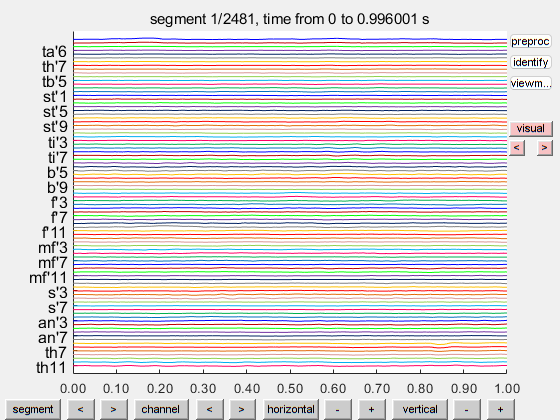

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.viewmode = 'vertical';
ft_databrowser([], DataPrep);

## redefine the resting block

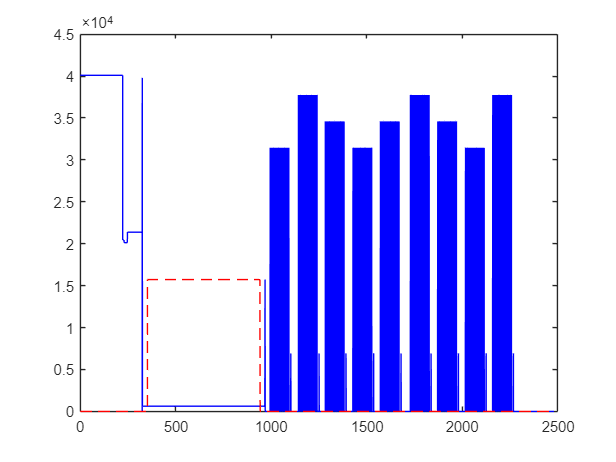

EventValue = unique(Event);
rsValue = 15721;
rsStart = 700000;
rsStart = rsStart + ceil(10*fsample);
rsEnd = rsStart + ceil(10*60*fsample-10*fsample);
rsPointer = zeros(size(Event));
rsPointer(rsStart:rsEnd) = 1;
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, rsValue*rsPointer, '--r');
hold off;

%% Construct data
rsSignals = Data.trial{1}(:, rsStart:rsEnd);
sampleinfo = [1, size(rsSignals, 2)];
rsTime = Data.time{1}(rsStart:rsEnd);
rsData.cfg = Data.cfg;
rsData.fsample = fsample;
rsData.label = Data.label;
rsData.hdr = Data.hdr;
rsData.trial{1} = rsSignals;
rsData.time{1} = rsTime;
rsData.sampleinfo = sampleinfo;
save([subID, '_task-resting_run-1_ieeg.mat'], 'rsData');
disp('******************************************************');

******************************************************


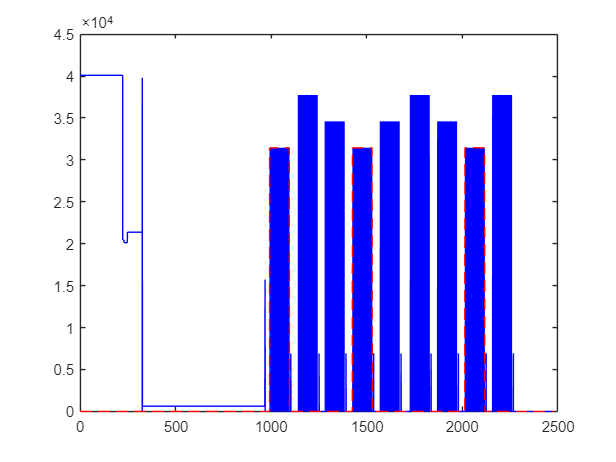

%% Redefine 0-back blocks
nb0Value = EventValue(13);
nb0Pointer = Event == nb0Value;
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Pointer = zeros(size(Event));
for nn = 1:length(nb0Start)
    nb0Pointer(nb0Start(nn)-ceil(3*fsample):nb0End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb0Value*nb0Pointer, '--r');
hold off;

% construct data
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Data.cfg = Data.cfg;
nb0Data.fsample = fsample;
nb0Data.label = Data.label;
nb0Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb0Start(nRun), nb0End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb0Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb0Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb0Data.sampleinfo(nRun, :) = sampleinfo;
    nb0Data.time{nRun} = nb0Time;
    nb0Data.trial{nRun} = nb0Signal;
end
save([subID, '_task-0back_run-1_ieeg.mat'], 'nb0Data', 'TRIG');
disp('******************************************');

******************************************


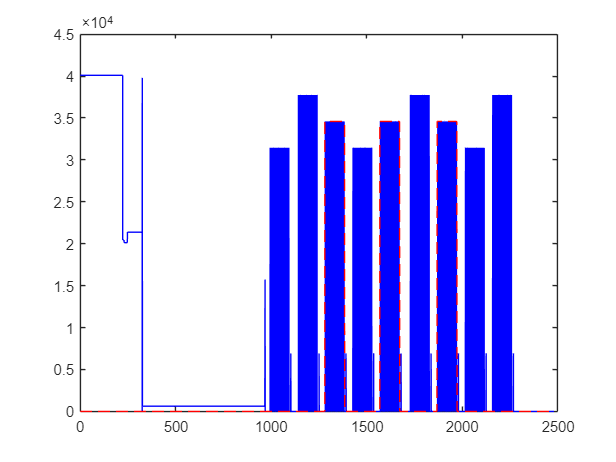

%% Redefine 1-back blocks
nb1Value = EventValue(14);
nb1Pointer = Event == nb1Value;
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Pointer = zeros(size(Event));
for nn = 1:length(nb1Start)
    nb1Pointer(nb1Start(nn)-ceil(3*fsample):nb1End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb1Value*nb1Pointer, '--r');
hold off;

% Construct data
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Data.cfg = Data.cfg;
nb1Data.fsample = fsample;
nb1Data.label = Data.label;
nb1Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb1Start(nRun), nb1End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb1Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb1Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb1Data.sampleinfo(nRun, :) = sampleinfo;
    nb1Data.time{nRun} = nb1Time;
    nb1Data.trial{nRun} = nb1Signal;
end
save([subID, '_task-1back_run-1_ieeg.mat'], 'nb1Data', 'TRIG');
disp('*************************************');

*************************************


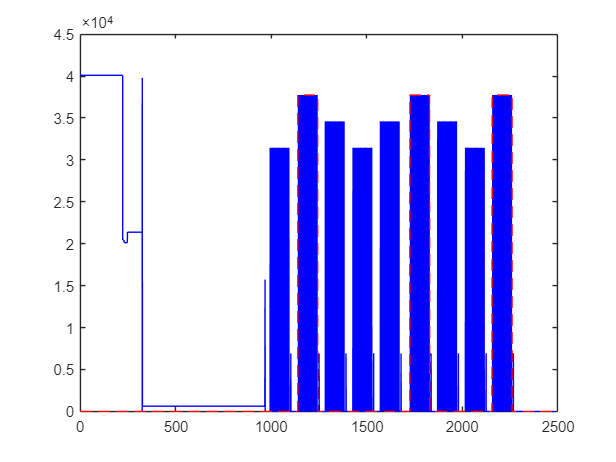

%% Redefine 2-back blocks
nb2Value = EventValue(15);
nb2Pointer = Event == nb2Value;
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Pointer = zeros(size(Event));
for nn = 1:length(nb2Start)
    nb2Pointer(nb2Start(nn)-ceil(3*fsample):nb2End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb2Value*nb2Pointer, '--r');
hold off;

% Construct data
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Data.cfg = Data.cfg;
nb2Data.fsample = fsample;
nb2Data.label = Data.label;
nb2Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb2Start(nRun), nb2End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb2Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb2Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb2Data.sampleinfo(nRun, :) = sampleinfo;
    nb2Data.time{nRun} = nb2Time;
    nb2Data.trial{nRun} = nb2Signal;
end
save([subID, '_task-2back_run-1_ieeg.mat'], 'nb2Data', 'TRIG');